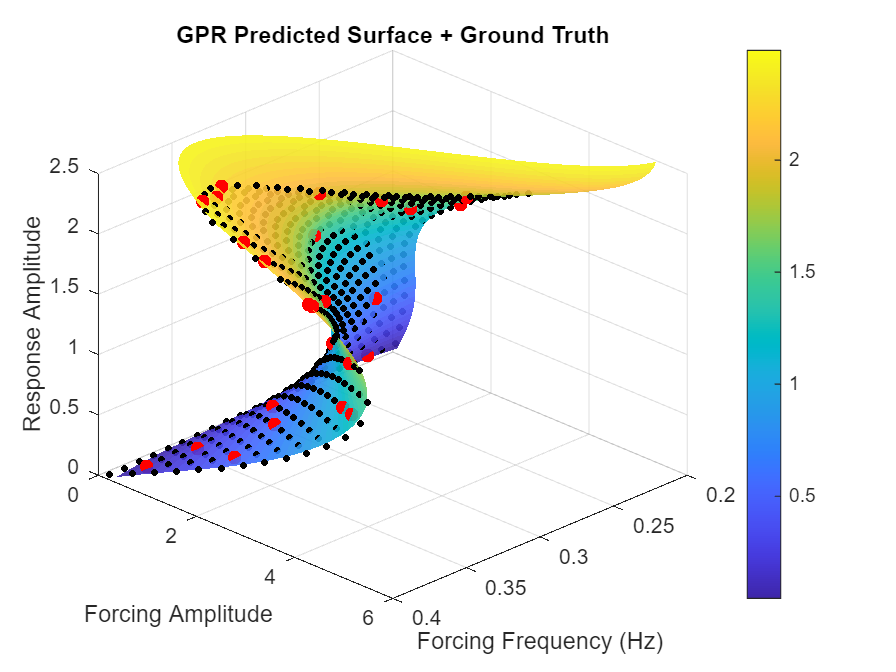

%% Load Data
load("data_save.mat");  % 'data' = [forcing_amp, forcing_freq, response_amp]

forcing_amp   = data(:, 1);  % dependent variable (what we predict)
forcing_freq  = data(:, 2);  % input
response_amp  = data(:, 3);  % input

%% Select Training Subset
n_train = 25;
idx_train = randperm(size(data, 1), n_train);

X_train = data(idx_train, [3, 2]);  % [response_amp, forcing_freq]
Y_train = data(idx_train, 1);      % forcing_amp

%% Train GPR Model
gpr_model = fitrgp(X_train, Y_train, ...
    'KernelFunction', 'squaredexponential', ...
    'Standardize', true);

%% Generate Prediction Grid
resp_range = linspace(min(response_amp), max(response_amp), 50);
freq_range = linspace(min(forcing_freq), max(forcing_freq), 50);
[RR, FF] = meshgrid(resp_range, freq_range);  % RR: response amp, FF: forcing freq

% Predict forcing amplitude
X_query = [RR(:), FF(:)];  % input = [response_amp, forcing_freq]
Y_pred = predict(gpr_model, X_query);  % predicted forcing_amp
AA = reshape(Y_pred, size(RR));  % Reshape to match grid

%% Plot Surface with Points
figure;
hold on;

% Plot GPR surface
surf(FF, AA, RR, 'EdgeColor', 'none', 'FaceAlpha', 0.9);

% Plot all ground truth in black
scatter3(forcing_freq, forcing_amp, response_amp, 10, 'k', 'filled');

% Plot selected training points in red
scatter3(X_train(:, 2), Y_train, X_train(:, 1), 40, 'r', 'filled');

xlabel('Forcing Frequency (Hz)');
ylabel('Forcing Amplitude');
zlabel('Response Amplitude');
title('GPR Predicted Surface + Ground Truth');
colorbar;
view(135, 30);
grid on;